# Logistic regression

Let's look at some examples of logistic regression for classification. The simplest case is in one dimension. Then we'll look at a two-dimensional case.

Generate 1-dimensional synthetic data in two classes.

n = 10; % number of observations in each class
x1 = sqrt(2.5)*randn(n,1) - 2; % first class
x2 = sqrt(2.5)*randn(n,1) + 2; % second class
x = [x1; x2];
y = [zeros(n,1); ones(n,1)];

Define the negative log likelihood function, which we write as


$$E(w) = \sum_{i=1}^n \left\{ y_i \log(1+\exp(-s_i)) + (1-y_i) \log(1+\exp(s_i)) \right\}$$


where $s_i = w^T \phi(x_i)$ and $\phi(x)$ is the vector of basis functions. For a linear discriminant, $\phi(x) = [1, x]^T$. To vectorize the negative log likelihood function, `phi` will be the matrix whose $i$th column is $\phi(x_i)$.

phi = [ones(1,2*n); x'];
nll_fun = @(w) y'*log(1+exp(-w'*phi)') + (1-y)'*log(1+exp(w'*phi)');

Call a MATLAB built-in unconstrained optimization function to find `w`. The `fminunc` function only evaluates the objective function and does not need the gradient of the objective function. The function also takes an initial guess for `w`.

w = fminunc(nll_fun, [0 1]')


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


w =    -0.0288
    1.5367


Plot the logistic function corresponding to the weights that were optimized for the data.

xx = -5:.01:5;
ss = w(1)+w(2)*xx;
yy = 1./(1+exp(-ss));
clf
plot(xx,yy);
hold on

Also plot the original data.

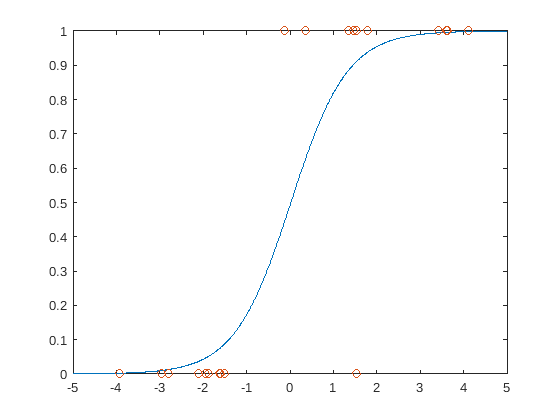

plot(x,y,'o');

Click on "Run Section" in this live script several times to see how the shape of the logistic function changes depending on the data. You can also change the variance of the generated data, which would control how much overlap there is in the data between the two classes.

### Two-dimensional example

Generate 2-dimensional synthetic data in two classes.

n = 20;
x = [randn(n,2)-.8; randn(n,2)+.8];
y = [zeros(n,1); ones(n,1)];

Set the basis functions to give us a linear discriminant. The negative log likelihood function defined here will work for any number of dimensions.

phi = [ones(1,2*n); x'];
nll_fun = @(w) y'*log(1+exp(-w'*phi)') + (1-y)'*log(1+exp(w'*phi)');

Call the optimizer with a zero initial guess for the weights. 

w = fminunc(nll_fun, [0 0 0]')


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


w =    -0.0526
    1.7296
    2.4667


Compute the logistic function on a two-dimensional mesh.

xx = -4:.01:4;
yy = -4:.01:4;
[x1, x2] = meshgrid(xx, yy);
s = w(1) + w(2)*x1 + w(3)*x2;
Z = 1./(1+exp(-s));

Plot the logistic function and the data points. The plot is interactive and you can rotate it to get a better picture of the logistic function in 2-D.

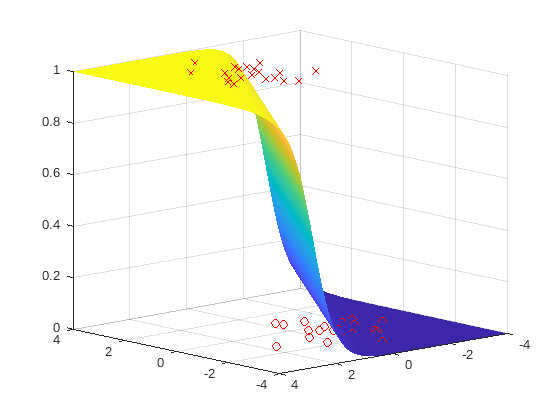

figure; clf
h = surf(xx, yy, Z);
set(h, 'edgecolor', 'none');
hold on
plot3(x( 1:20,1),x( 1:20,2),y( 1:20),'ro');
plot3(x(21:40,1),x(21:40,2),y(21:40),'rx');
view([-132.300 13.200])

Plot the decision surface, which is just a straight line for this 2-D example. Also plot the data points.

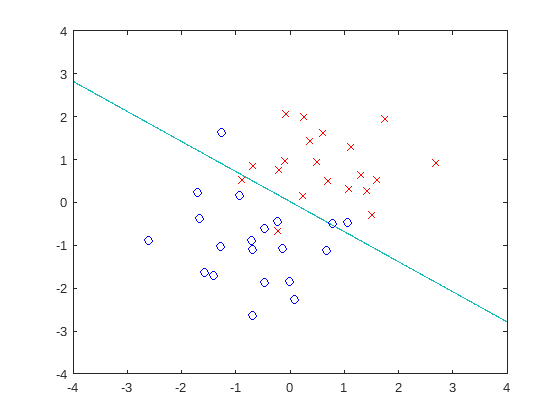

figure; clf
contour(xx, yy, Z, [0.5 0.5])
hold on
plot(x( 1:20,1),x( 1:20,2),'bo');
plot(x(21:40,1),x(21:40,2),'rx');

Click on "Run Section" in this live script several times to see the result for other examples of the synthetic data.

### Taking it further

For the two-dimensional case, compare the discriminant that is found with the optimal discriminant for the distribution of the data.